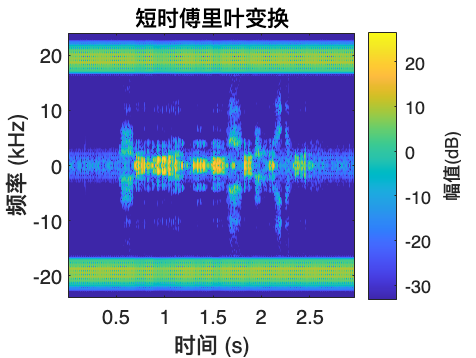


Fs=48000;
fs=48000;

x=audioread('receive/1013/google2record1641029660107.wav');

% wlen=1024
% inc=512
% [f0,idx] = pitch(x,fs, 'WindowLength',wlen,'OverlapLength',inc);%求取语音的基音频率
% fn1=size(f0,1);
% result_f0=f0(find(f0<400));%筛选符合条件的基音频率
% figure()
% plot(result_f0);%绘制基音频率
% title('基音频率f0')
% xlabel('帧')
% ylabel('频率/Hz')
% axis([0 fn1 0 400])%设置坐标轴范围

% 
stft(x, Fs,'FFTLength',2048);

% window=256;%滑动窗大小
% nfft=2048;
% noverlap=220;%重叠样本数为100重叠99平移样本,每隔1个单位画一个框计算
% spectrogram(x,window,noverlap, fs, 'yaxis');  
% ax=gca;
% ylim(ax, [0.6, 0.9]);

x=lowpass(x, 10000, Fs);
x=x(20000:68000)

x =    -0.0027
   -0.0030
   -0.0034
   -0.0037
   -0.0041
   -0.0044
   -0.0045
   -0.0047
   -0.0046
   -0.0046


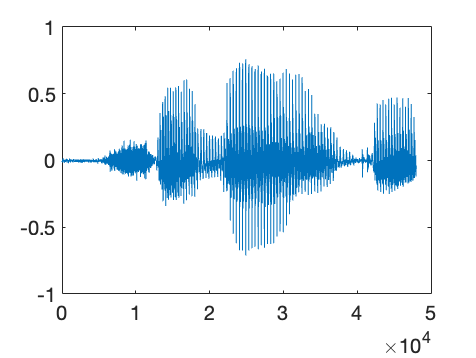

figure;
plot(x)

bank=melbankm(24,960,Fs,0,0.5,'t');

函数或变量 'melbankm' 无法识别。

%Mel滤波器的阶数为24，fft变换的长度为882，采样频率为44100Hz
%归一化mel滤波器组系数
bank=full(bank);%稀疏矩阵转为正常矩阵的存储方式
bank=bank/max(bank(:));
for k=1:12 %计算出离散余弦变换的系数
n=0:23;
dctcoef(k,:)=cos((2*n+1)*k*pi/(2*24));
end
x=filter([1 -0.97],1,x);%预加重滤波器
figure;
plot(x)
x=enframe(x,960,480);%语音信号分帧,对x每882点分为一帧，平移441个点后再取下一帧
%计算每帧的MFCC参数
for i=1:size(x,1)
    y=x(i,:); %取出一帧信号
    s=y'.*hamming(960); %加窗
    t=abs(fft(s)); %先fft后取模
    t=t.^2; %取平方
%     c=dctcoef*log(bank*t(1:481)); %通过Mel滤波器、对数运算和DCT
    c=log(bank*t(1:481)); 
    m(i,:)=c'; %存储结果
end
figure;
plot(y);
figure;
plot(m)
% m
% figure;
% plot(mean(m'))
